## Pekeris Waveguide

- Isovelocity

- Flat sea surface and seafloor

- range-independent sediment

- point source (ability to change depth)

- single reciever (ability to change depth and range)

- Fixed source level (0 dB)

- Signal Type? Gaussian shaded CW?

- Attenuation in the medium?

- Water depth? 50 m? Allow user to change?

### Ray calculation for the range-independent, isovelocity waveguide

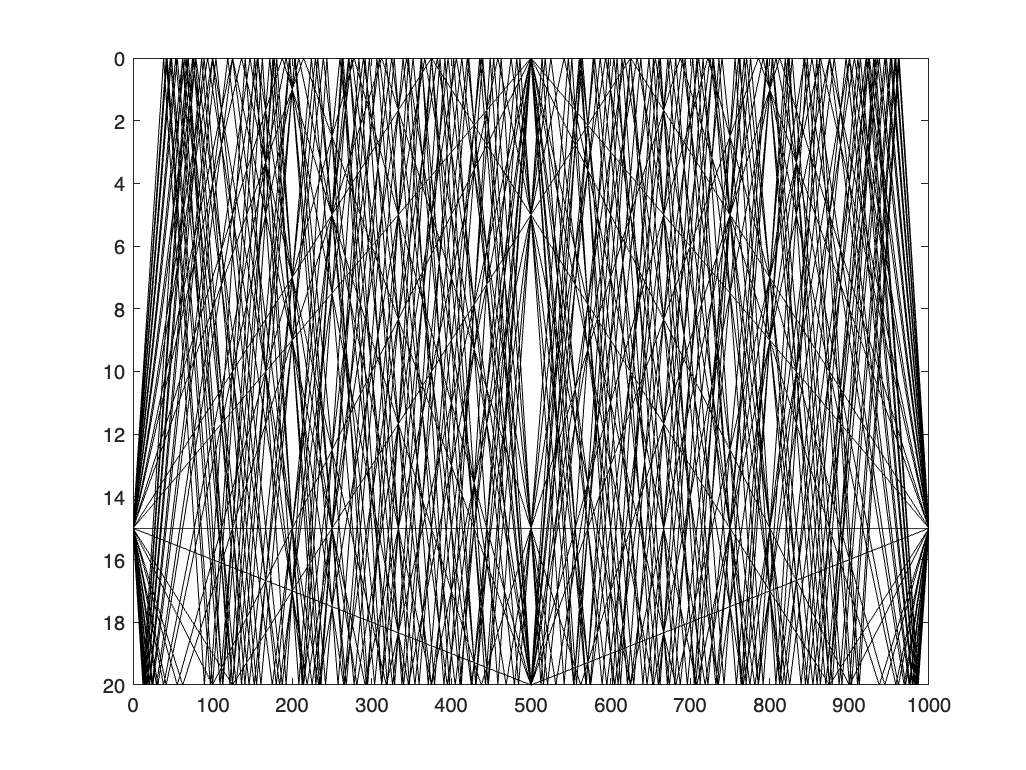

D = 20;
zSource = 15;
rRec = 1000;
zRec = 15;
rSource = 0;

f = 100000;
cw = 1500;
cp = 1.15*cw;
rhop = 2.051;
rhow = 1;
alphap = 317.1;
k = 2*pi*f/cw;

Nrays = 40;

NrayCalc = floor(Nrays/4)*4;

if NrayCalc < Nrays
    NrayCalc = NrayCalc + 4; 
end

NraySets = NrayCalc/4;

figure(1)
clf

figure(2)
clf

tVAll = [];
pVAll = [];

for jR = 1:NraySets

    zV(1) = 2*D*(jR-1) + zSource - zRec;
    zV(2) = 2*D*jR - zSource - zRec;
    zV(3) = -(2*D*(jR-1) + zSource + zRec);
    zV(4) = -(2*D*jR - zSource + zRec);
    
    for jV = 1:4

        rAngle(jV) = atan(abs(zV(jV)/(rRec - rSource)));
        RC1(jV) = RCoeff(f, rAngle(jV)*180/pi, cw, cp, rhop/rhow, rhow, alphap);
        rV(jV) = sqrt((rRec - rSource).^2 + zV(jV).^2);
        tV(jV) = rV(jV)/cw;

    end

    pV(1) = ((-RC1(1)).^((jR-1))).*exp(1i*k*rV(1))/rV(1);
    pV(2) = ((-RC1(2)).^((jR-1))).*RC1(2).*exp(1i*k*rV(2))/rV(2);
    pV(3) = -((-RC1(3)).^((jR-1))).*exp(1i*k*rV(3))/rV(3);
    pV(4) = -((-RC1(4)).^((jR-1))).*RC1(4).*exp(1i*k*rV(4))/rV(4);


    mV = -zV./(rRec - rSource);
    bV = zRec - mV*rRec;
  
    L1 = [2*(jR-1):-1:1]*D;
    L2 = [(2*jR - 1):-1:1]*D;
    L3 = -[[2*(jR-1):-1:1]*D,0];
    L4 = -[[(2*jR - 1):-1:1]*D,0];

    % rI1 = (zV(1)+zRec - L1)./tan(rAngle(1));
    rI1 = (L1 - bV(1))./mV(1);
    zI1 = repmat([0 D],1,jR-1);

    rI2 = (L2 - bV(2))./mV(2);
    zI2 = [D,repmat([0 D],1,jR-1)];

    rI3 = (L3 - bV(3))./mV(3);
    zI3 = [0,repmat([D 0],1,jR-1)];

    rI4 = (L4 - bV(4))./mV(4);
    zI4 = [repmat([D 0],1,jR)];

    ray1_r = [0,rI1,rRec];
    ray1_z = [zSource,zI1,zRec];

    ray2_r = [0,rI2,rRec];
    ray2_z = [zSource,zI2,zRec];

    ray3_r = [0,rI3,rRec];
    ray3_z = [zSource,zI3,zRec];

    ray4_r = [0,rI4,rRec];
    ray4_z = [zSource,zI4,zRec];

    figure(1)
    hold on
    plot(ray1_r,ray1_z,'k')
    plot(ray2_r,ray2_z,'k')
    plot(ray3_r,ray3_z,'k')
    plot(ray4_r,ray4_z,'k')
    hold off

    figure(2)
    hold on
    plot(tV,20*log10(abs(pV)),'ko')
    hold off

    %%

    tVAll = [tVAll, tV];
    pVAll = [pVAll, pV];

end

figure(1)

a = gca;
a.YDir = 'reverse';
% axis equal
a.YLim = [0 D];
a.XLim = [rSource,rRec];
box on

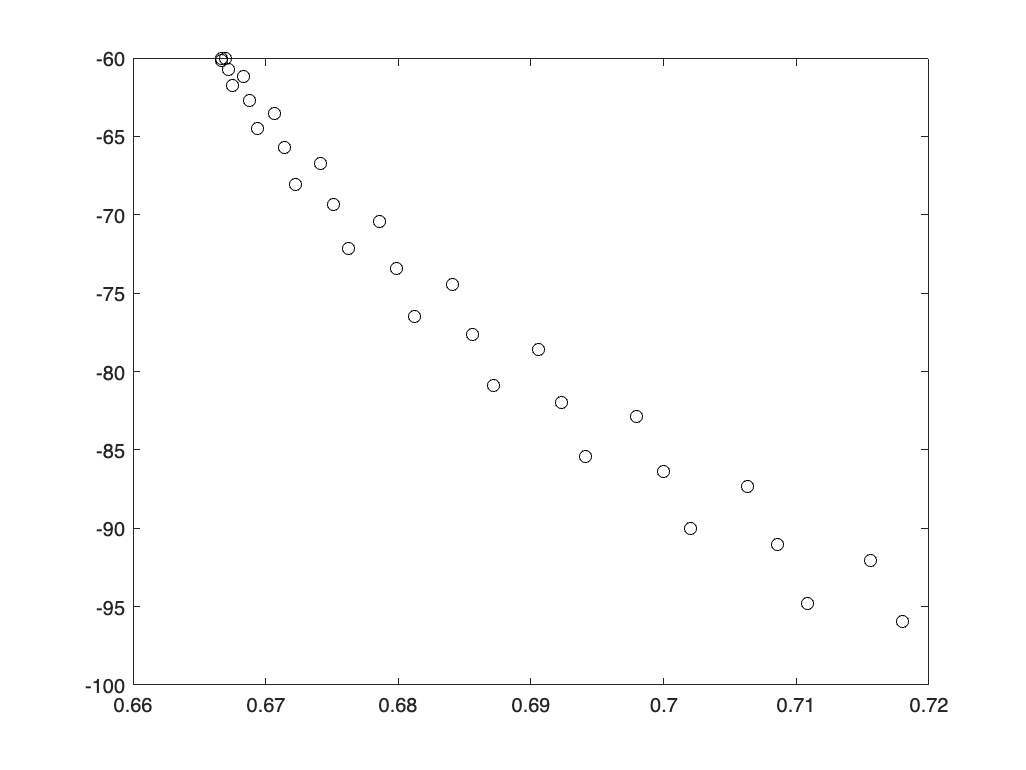


figure(2)

a1 = gca;
box on

### Time Series Calculation

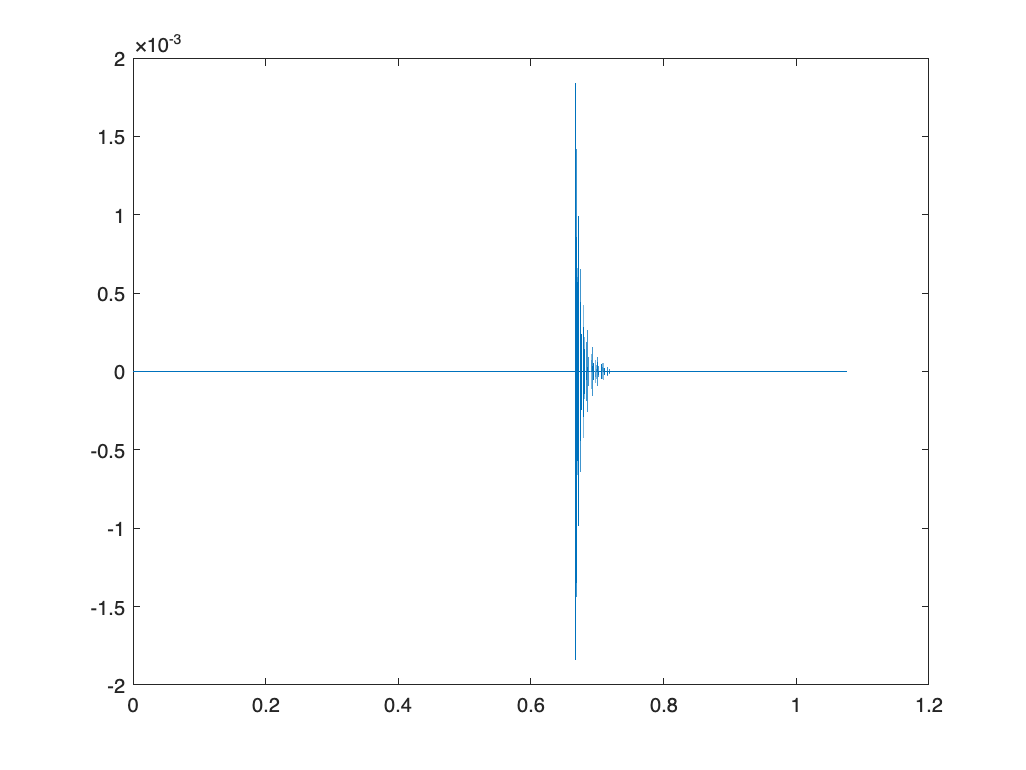

dt = (1/f)/10;
t1 = [0:dt:1.5*tV(4)];

tau = 4/f;

% CW_pulse = 0.*t1;
Gauss_pulse = 0.*t1;

for jV = 1:length(tVAll)

    % CW_pulse = CW_pulse + CW_pulse_propagation(pVAll(jV),t1,tVAll(jV),f,tau);
    Gauss_pulse = Gauss_pulse + Gaussian_pulse_propagation(pVAll(jV),t1,tVAll(jV),f,tau);

end

figure(3)
plot(t1,Gauss_pulse)

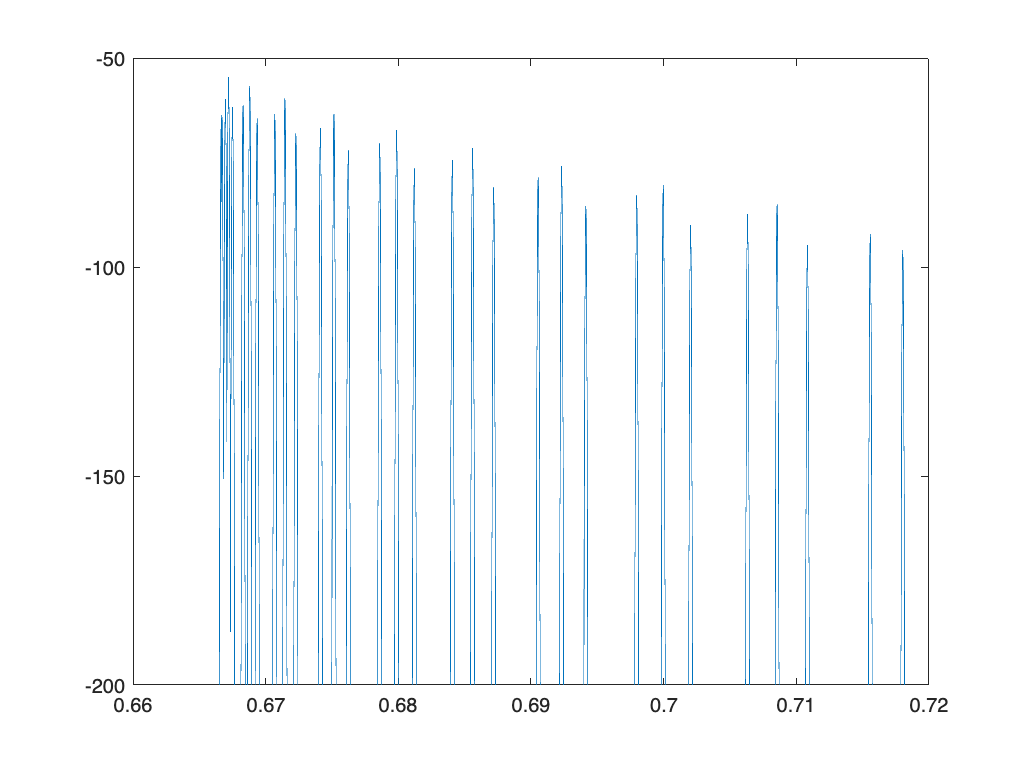


figure(4)
plot(t1,20*log10(abs(hilbert(Gauss_pulse))))

a2 = gca;
a2.YLim = [-200 -50];


10*log10(sum(abs(Gauss_pulse).^2))

ans = -35.2920